# Actividad 1.12 (Modelado Cinemático de Piernas)

**Obtener **la matriz de  transformación **homogénea  T, **la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

- Para cada caso de definen las rotaciones y trazlaciones que hace el sistema y las pocisiones en las que hace el recorrido para poder hacer la simulacion correcta.

%Limpieza de pantalla
clear all
close all
clc

## sistema 1

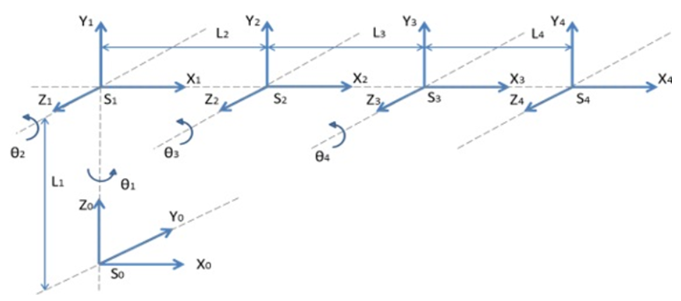

%Calculamos las matrices de transformación homogénea
%H0=SE3;
%H1=SE3(rotx(pi/2), [0 0 4]);
%H2=SE3(rotx(0), [3 0 0]);
%H3=SE3(rotx(0), [3 0 0]);
%H4=SE3(rotx(0), [3 0 0]);

%H20= H1*H2*H3;
%H30= H20*H4 %Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
%x=[0 0 3 6 9 ];
%y=[0 0 0 0 0 ];
%z=[0 4 4 4 4 ];

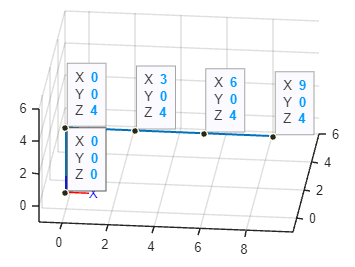

## Sistema 2

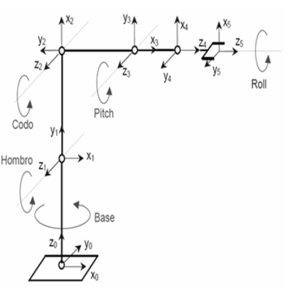

%Calculamos las matrices de transformación homogénea
%H0=SE3;
%H1=SE3(rotx(pi/2), [0 0 3]);
%H2=SE3(rotz(pi/2), [0 0 3]);
%H3=SE3(rotx(0), [0 2 0]);
%H4=SE3(rotx(-pi/2), [1 0 0]);
%H5=SE3(rotx(0), [1 0 0]);

%H20= H1*H2*H3*H4;
%H30= H20*H5 %Matriz de transformación homogenea global de 3 a 0 
%Coordenadas de la estructura de translación y rotación
%x=[0 0 0 2 3 4 ];
%y=[0 0 0 0 0 0];
%z=[0 3 6 6 6 6];


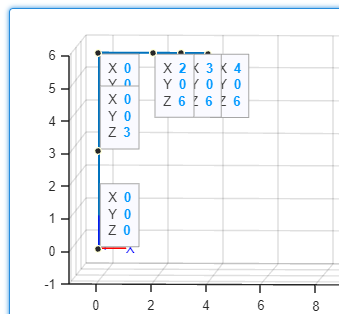

## Sistema 3

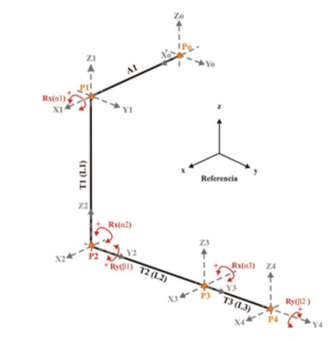

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(0), [3 0 0]);
H2=SE3(rotz(0), [0 0 -4]);
H3=SE3(rotx(0), [0 3 0]);
H4=SE3(rotx(0), [0 2 0]);

H20= H1*H2*H3;
H30= H20*H4 %Matriz de transformación homogenea global de 3 a 0 

 

H30 = 
         1         0         0         3
         0         1         0         5
         0         0         1        -4
         0         0         0         1



%Coordenadas de la estructura de translación y rotación
x=[0 3 3 3 3 ];
y=[0 0 0 3 5 ];
z=[0 0 -4 -4 -4 ];

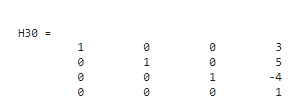

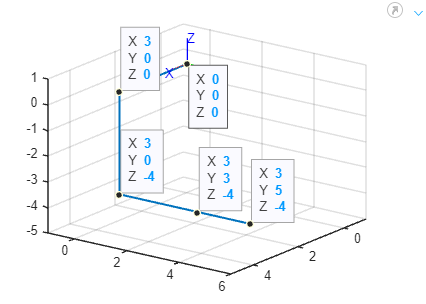

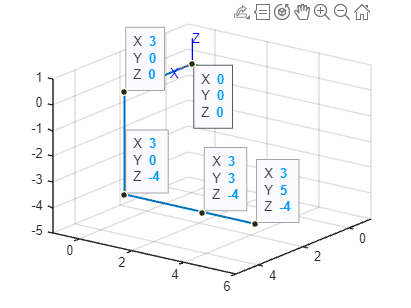

plot3(x, y, z,'LineWidth', 1.5); axis([-1 5 -1 6 -5 1]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 5 -1 6 -5 1])